# CONDITION TOPOPLOTS*

## First retreive Master Data Set

cog_task_list = {'PVT'};
df_long =  dflong('cogtestlist',cog_task_list,'getd2cdf',false);

## INITIATE

clearvars -except df_long; clc;



Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done



% SETTINGS
cogtask = 'PVT';
bandname  = 'delta';
IV = 'gpsd'; 
DV = 'clust'; 
numlevels = 3;
t=1;
bonfcorrect = 2;
categwthn_condition = true;
categwthn_subject = true;
condition2analyze = 'control';
run_sbj_test = true;
% INIT
DV_mean =  sprintf('mean_%s',DV);
IV_level  = sprintf('%s_level',IV);
desired_vars = [{DV},{IV},experimentalvars()];

% LOAD DATA
df     = dflong2wide(df_long, cogtask, {'baseline', 'control','light'}, bandname, t,'keepchannels',true);
df = df(:,desired_vars);

% CATEGORIZE THE IV.
df= categcolumn(df,IV,numlevels,"condition",categwthn_condition,"subject",categwthn_subject);
df.(IV_level) = findgroups(df.(IV_level));
[df_bsl, df_ctr, df_lgt] = splitdfbycondition(df);
df=dfrmcats(df);
df_hgh = df(df.(IV_level)==numlevels & (df.condition == "baseline" | df.condition ==condition2analyze),:);
df_low = df(df.(IV_level)==1 & (df.condition == "baseline" | df.condition ==condition2analyze),:);




% SUBJECT IDS
sbjid_list = unique(df.sbj);
numsubj = numel(sbjid_list);
example_subject = sbjid_list(1);




# ANALYSIS: Differences in DV among nodes with high IV during baseline only

% Differences in DV among nodes with high IV during baseline only


% FUNCTIONS

% CREATE DATA FRAME FOR TESTING
inittable_anz2 = @(ch, DV_dif,DV_bl, DV_ctr, sbjid,ivlev) table(...
    ch,...    
    repmat(sbjid,numel(ch),1),...
    DV_dif,...
    DV_bl,...
    DV_ctr,...
    repmat(ivlev,numel(ch),1)...
    );

D = table;
T_within = table;


for j = 1:numsubj
    sbjid =  sbjid_list(j);
    df_sbj_bsl = df(df.sbj == sbjid & df.condition == 'baseline',:);
    df_sbj_ctr = df(df.sbj == sbjid & df.condition == 'control',:);
    
    getchan = @(desired_level) df_sbj_bsl.chan(df_sbj_bsl.(IV_level) == desired_level & df_sbj_bsl.condition == 'baseline');
    getDV    = @(df_cond,desired_level) df_cond.(DV)(getchan(desired_level));

    % Change in DV for nodes with low IV during baseline
    ch  =  getchan(1);

    DV_iv_bsl = getDV(df_sbj_bsl,1);
    DV_iv_ctrl = getDV(df_sbj_ctr,1);
    dDV = DV_iv_bsl - DV_iv_ctrl ;
    t_ivlow = inittable_anz2(ch,dDV,DV_iv_bsl,DV_iv_ctrl,sbjid,1);

    % Change in DV for nodes with High IV during baseline
    ch  = getchan(numlevels );   
    DV_iv_bsl = getDV(df_sbj_bsl,numlevels);
    DV_iv_ctrl = getDV(df_sbj_ctr,numlevels);
    dDV = DV_iv_bsl  - DV_iv_ctrl ;
    t_ivhgh = inittable_anz2(ch,dDV,DV_iv_bsl,DV_iv_ctrl,sbjid,numlevels);    
    D = [D;t_ivlow;t_ivhgh];

end
DV_diff = sprintf('%s_diff',DV);
DV_bsl = sprintf('%s_bsl',DV);
DV_ctr = sprintf('%s_ctr',DV);
IV_at_bsl = sprintf('%s_bsl',IV)

D.Properties.VariableNames = {'chan','sbj',DV_diff,DV_bsl, DV_ctr,IV_at_bsl};
Ylow_bsl = D.(DV_bsl)( (D.(IV_at_bsl) == 1))
Ylow_ctr = D.(DV_ctr)( (D.(IV_at_bsl) == 1));
Yhigh_bsl = D.(DV_bsl)( (D.(IV_at_bsl) == numlevels));
Yhigh_ctr = D.(DV_ctr)( (D.(IV_at_bsl) == numlevels));

IV_at_bsl = 'gpsd_bsl'

Ylow_bsl =     0.0427
    0.0525
    0.0387
    0.0371
    0.0506
    0.0534
    0.0495
    0.0552
    0.0689
    0.0770


DV_indicator = [DV,'_Indicator'];
DT = stack(D,3:5,'NewDataVariableName',DV);
DT(DT.(DV_indicator) == DV_diff,:) = [];
DT = dfrmcats(DT);



INIT FIGS

close all
figure('Visible','on')
T = tiledlayout(4,4);
T.Title.String = sprintf('[%s %s] after waking (%s, %s only)\namong nodes with high levels of %s during *baseline*', bandname, upper(DV), cogtask,  condition2analyze, upper(IV));
T.Title.Interpreter = "none";
T.Title.FontWeight = "bold";

# ANALYSIS

##  [AVERAGE VALUE OF NODES WITH HIGH IV VALUES FOR EACH SUBJECT]  VS. [AVERAGE VALUE OF NODES WITH *LOW* IV VALUES FOR EACH SUBJECT]

## ALLNODES OF ALL SUBJECTS WITH LOW IV VALUES DURING BASELINE]. WE USE T-TEST(LOOKS NORMAL, AND DEPENDENT SAMPLES):


% ANALYSIS: [AVERAGE VALUE OF NODES WITH HIGH IV VALUES FOR EACH SUBJECT]
% VS. [AVERAGE VALUE OF NODES WITH *LOW* IV VALUES FOR EACH SUBJECT][ALL
% NODES OF ALL SUBJECTS WITH LOW IV VALUES DURING BASELINE]. WE USE T-TEST
% (LOOKS NORMAL, AND DEPENDENT SAMPLES):



DT_mean = groupsummary(DT,{'sbj',(IV_at_bsl),DV_indicator},'mean',DV)

getgroup = @(iv_level,condition) DT_mean.(DV_mean)( DT_mean.(IV_at_bsl) == iv_level & DT_mean.(DV_indicator) == [DV,'_',condition])
Ylow_bsl = getgroup(1,'bsl');
Ylow_ctr = getgroup(1,'ctr');
Yhigh_bsl = getgroup(numlevels,'bsl');
Yhigh_ctr = getgroup(numlevels,'ctr');


p_dYlow = signrank(Ylow_bsl,Ylow_ctr);
p_dYhigh = signrank(Yhigh_bsl,Yhigh_ctr);


DT_mean = 44×5 table
    sbj     gpsd_bsl    clust_Indicator    GroupCount    mean_clust
    ____    ________    _______________    __________    __________

    2952       1           clust_bsl           8          0.047479 
    2952       1           clust_ctr           8          0.033893 
    2952       3           clust_bsl           8          0.046735 
    2952       3           clust_ctr           8          0.042235 
    2954       1           clust_bsl           8          0.053082 
    2954       1           clust_ctr           8          0.046577 
    2954       3           clust_bsl           8          0.063003 
    2954       3           clust_ctr           8          0.052363 
    2956       1           clust_bsl           8          0.071349 
    2956       1           clust_ctr           8          0.

% BOX PLOT
nexttile

getgroup = function_handle with value:
    @(iv_level,condition)DT_mean.(DV_mean)(DT_mean.(IV_at_bsl)==iv_level&DT_mean.(DV_indicator)==[DV,'_',condition])


boxchart(DT_mean.(IV_at_bsl),DT_mean.(DV_mean),'GroupByColor',DT_mean.(DV_indicator))
hold on;

dx_plot = zeros(numel(Ylow_bsl),1)+.25;
scatter(1-dx_plot,Ylow_bsl,'filled','MarkerFaceColor','k');
scatter(1+dx_plot,Ylow_ctr,'filled','MarkerFaceColor','r');
scatter(numlevels-dx_plot,Ylow_bsl,'filled','MarkerFaceColor','k');
scatter(numlevels+dx_plot,Ylow_ctr,'filled','MarkerFaceColor','r');
xlabel(sprintf('Channel''s level of %s %s',bandname,upper(IV)))
ylabel(sprintf('%s %s',bandname, DV));

% PLOT HISTOGRAM COMPARING THE DV OF LOW IV NODES
nexttile;
hold on;
histogram(Ylow_bsl,15,'FaceColor','k');
histogram(Ylow_ctr,15);
legend({'Channels during baseline','during control'})
if p_dYlow<(.05/2)
    title_str = sprintf('%s of nodes with LOW %s (sig!!!)',upper(DV),upper(IV));
        fontcolor = 'g';
    
else
    title_str = sprintf('%s of nodes with LOW %s (ns)',upper(DV),upper(IV));
        fontcolor = 'k';
    
end
 
title(title_str,'Interpreter','none','color',fontcolor);
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))

% PLOT HISTOGRAM COMPARING THE DV OF HIGH IV NODES
nexttile;
hold on;
histogram(Yhigh_bsl,15,'FaceColor','k');
histogram(Yhigh_ctr,15);
if p_dYhigh<(.05/2)
    title_str = sprintf('%s of nodes with HIGH %s (sig!!)',upper(DV),upper(IV));
        fontcolor = 'g';
    
else    
    title_str = sprintf('%s of nodes with HIGH %s (ns)',upper(DV),upper(IV));
        fontcolor = 'k';
    
end

title(title_str,'Interpreter','none','color',fontcolor);


D_mean = groupsummary(D,["sbj",IV_at_bsl],"mean",DV_diff); 
DV_diff_mean = sprintf('mean_%s',DV_diff');

xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))


# ANALYSIS:

##  [ALL NODES OF ALL SUBJECTS WITH HIGH IV VALUES DURING BASELINE] VS. [ALL NODES OF ALL SUBJECTS WITH LOW IV VALUES DURING BASELINE].

## WE USE T-TEST (LOOKS NORMAL, AND DEPENDENT SAMPLES):

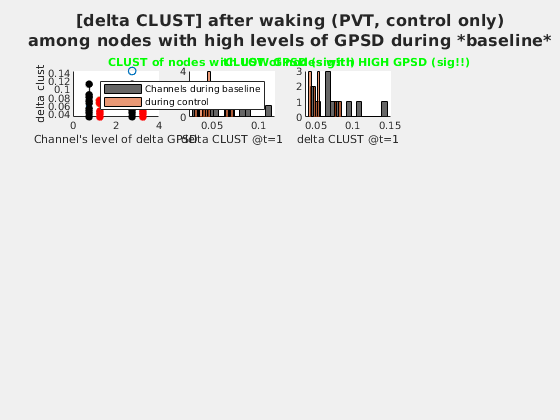

% ANALYSIS: [ALL NODES OF ALL SUBJECTS WITH HIGH IV VALUES DURING BASELINE]
% VS. [ALL NODES OF ALL SUBJECTS WITH LOW IV VALUES DURING BASELINE].
% WE USE T-TEST (LOOKS NORMAL, AND DEPENDENT SAMPLES):



p_dYhigh = ttest2(Yhigh_bsl,Yhigh_ctr);



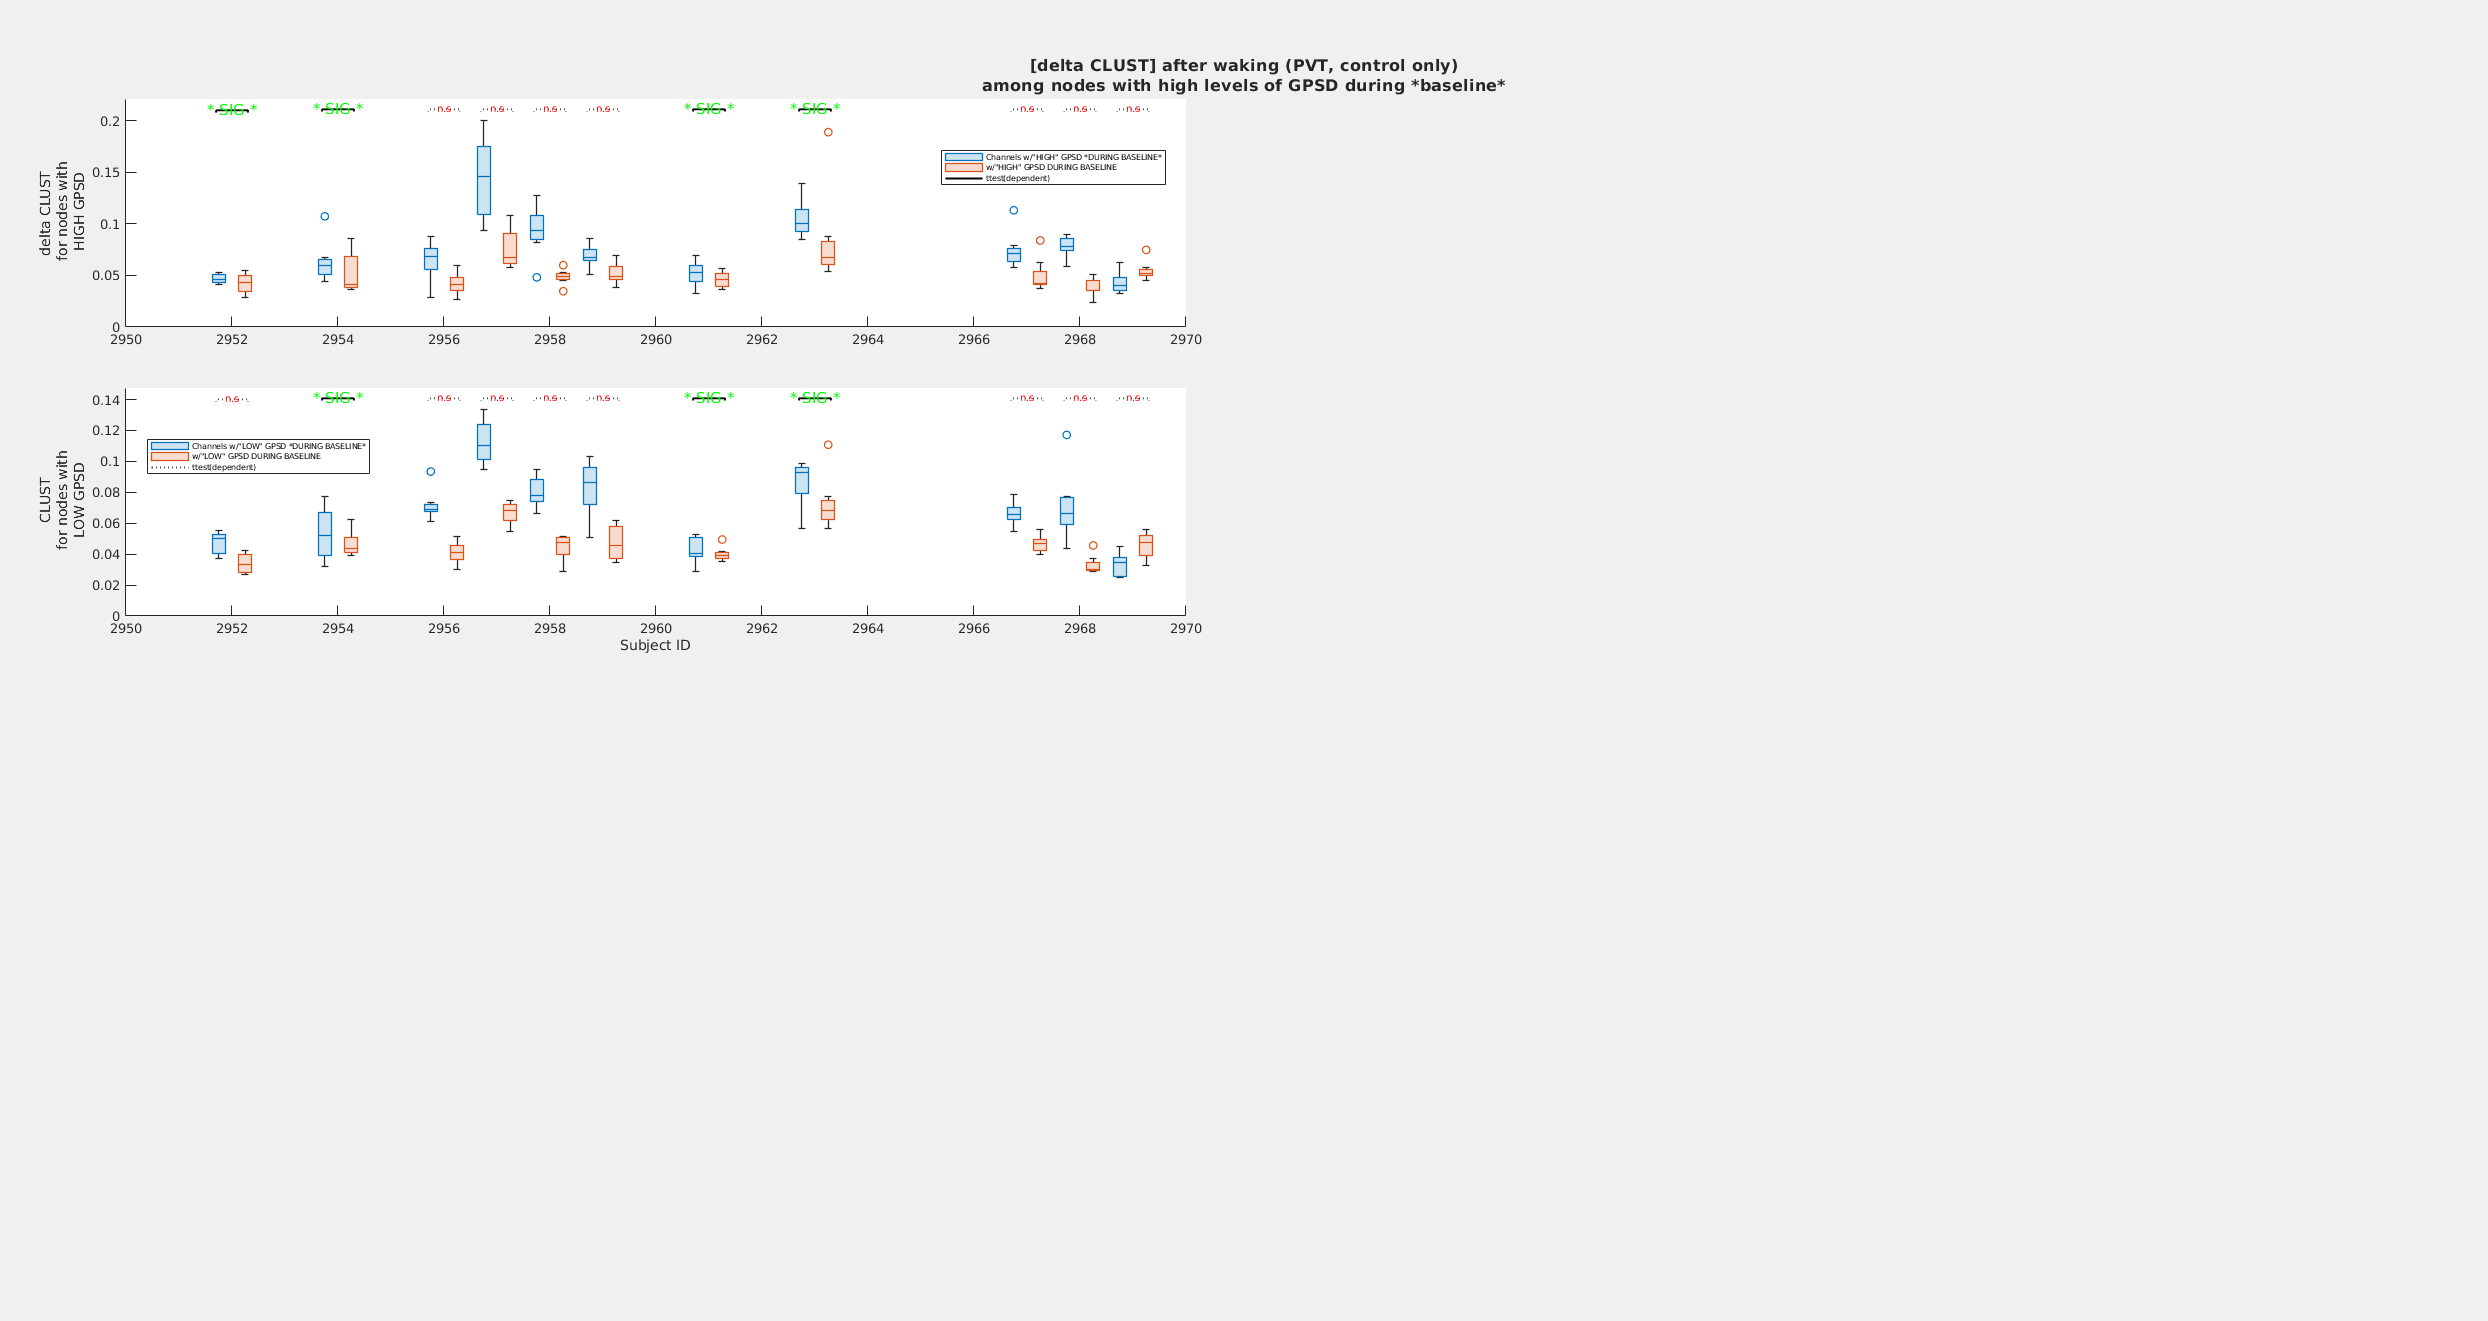

getsbj = function_handle with value:
    @(iv_level,condition,subject)DT.(DV)(DT.(IV_at_bsl)==iv_level&DT.(DV_indicator)==[DV,'_',condition]&DT.sbj==subject)


p = 0

p = 1

p = 0

p = 0

p = 1

p = 1

p = 1

p = 1

p = 1

p = 1

p = 1

p = 1

p = 0

p = 0

p = 0

p = 0

p = 1

p = 1

p = 1

p = 1

p = 1

p = 1

% PLOT BOX
ax = nexttile; hold on;
boxchart(DT.(IV_at_bsl),DT.(DV),'GroupByColor',DT.(DV_indicator));

dx_plot = zeros(numel(Ylow_bsl),1)+.25;
scatter(1-dx_plot,Ylow_bsl,'filled','MarkerFaceColor','k','SizeData',5);
scatter(1+dx_plot,Ylow_ctr,'filled','MarkerFaceColor','r','SizeData',5);
scatter(numlevels-dx_plot,Ylow_bsl,'filled','MarkerFaceColor','k','SizeData',5);
scatter(numlevels+dx_plot,Ylow_ctr,'filled','MarkerFaceColor','r','SizeData',5);

legend({sprintf('%s during BASELINE',upper(DV)),'during CTRL'});
ylabel(sprintf('%s %s',bandname, DV));
xlabel(sprintf('Channel''s level of %s %s',bandname,upper(IV)))

Ylow_bsl =     0.0427
    0.0525
    0.0387
    0.0371
    0.0506
    0.0534
    0.0495
    0.0552
    0.0689
    0.0770


ax.XTick = [1,3];
ax.XTickLabel = {sprintf('Channels w/ "low" %s',upper(IV)), sprintf('Channels w/ "HIGH" %s',upper(IV))};


% PLOT HISTOGRAM COMPARING THE DV OF LOW IV NODES
p_dYlow = ttest2(Ylow_bsl,Ylow_ctr);
nexttile;
hold on;
histogram(Ylow_bsl,15,'FaceColor','k');
histogram(Ylow_ctr,15);

legend({'Channels during baseline','during control'})
if p_dYlow<(.05/2)
    title_str = sprintf('%s of nodes with LOW %s (sigg!!!)',upper(DV),upper(IV));
    fontcolor = 'g';
    
else
    title_str = sprintf('%s of channels w/LOW %s (ns)',upper(DV),upper(IV));
    fontcolor = 'k';
end
 
title(title_str,'Color',fontcolor);
xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'During baseline','during control'})

% PLOT HISTOGRAM COMPARING THE DV OF HIGH IV NODES

nexttile;
hold on;
histogram(Yhigh_bsl,15,'FaceColor','k');
histogram(Yhigh_ctr,15);
if p_dYhigh<(.05/2)
    title_str = sprintf('%s of nodes with HIGH %s (sig)',upper(DV),upper(IV));
    fontcolor = 'g';
    
else
    title_str = sprintf('%s of nodes with HIGH %s (ns)',upper(DV),upper(IV));
        fontcolor = 'k';

end

xlabel(sprintf('%s %s @t=%d',bandname, upper(DV),t))
legend({'During baseline','during control'})

title(title_str,'Interpreter','none','color',fontcolor);


## FOR EACH SUBJECT [ALL NODES WITH HIGH IV VALUES DURING BASELINE]  VS. [ALL NODES WITH LOW IV VALUES DURING BASELINE]. WE USE RANK SUM TEST, DUE TO LOW SAMPLE SIZE, AND DEPENDENT (ALTHOUGH THIS IS DEBATABLE)

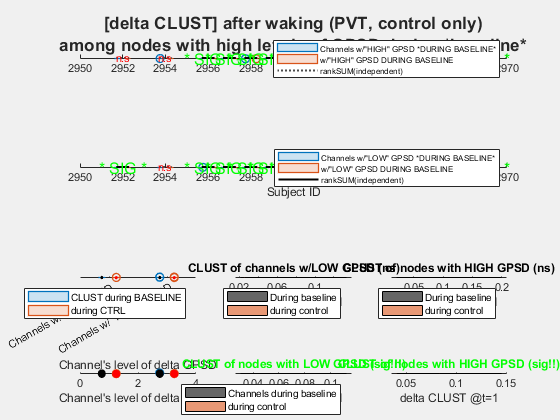


% ANALYSIS: FOR EACH SUBJECT [ALL NODES WITH HIGH IV VALUES DURING
% BASELINE] VS. [ALL NODES WITH LOW IV VALUES DURING BASELINE]. WE USE RANK
% SUM TEST, DUE TO LOW SAMPLE SIZE, AND INDEPENDENT (ALTHOUGH THIS IS
% DEBATABLE)

plotsbjbox = @(df_loworhigh) boxchart(df_loworhigh.sbj,df_loworhigh.(DV),'GroupByColor',df_loworhigh.condition);


ax_box_high = nexttile(1,[1 2]);
DT_high = DT(DT.(IV_at_bsl)==numlevels,:);
boxchart(DT_high.sbj,DT_high.(DV),'GroupByColor',DT_high.(DV_indicator));
hold on;

ax_box_low = nexttile(5,[1 2]);

DT_low = DT(DT.(IV_at_bsl)==1,:);
boxchart(DT_low.sbj,DT_low.(DV),'GroupByColor',DT_low.(DV_indicator));
hold on;



getsbj = @(iv_level,condition,subject) DT.(DV)( DT.(IV_at_bsl) == iv_level & DT.(DV_indicator) == [DV,'_',condition] &  DT.sbj == subject)    

for j = 1:numsubj
    sbjid = sbjid_list(j);

    Y_bsl = getsbj(numlevels,'bsl',sbjid);
    Y_ctr = getsbj(numlevels,'ctr',sbjid);

    if run_sbj_test
        axes(ax_box_high);        
        p = ttest(Y_bsl,Y_ctr)
        h = sigstar({[sbjid-.3 sbjid+.3]});
        fixsigstar(h,p,1)
    end

    Y_bsl = getsbj(1,'bsl',sbjid);
    Y_ctr = getsbj(1,'ctr',sbjid);

    if run_sbj_test
        axes(ax_box_low)    ;    
        p = ttest(Y_bsl,Y_ctr)
        h = sigstar({[sbjid-.3 sbjid+.3]});
        fixsigstar(h,p,1)
    end

end

ylabel(ax_box_high,sprintf('%s %s\n for nodes with\n HIGH %s',bandname,upper(DV),upper(IV)),'Interpreter','none')
legend(ax_box_high, {sprintf('Channels w/"HIGH" %s *DURING BASELINE*',upper(IV)), sprintf('w/"HIGH" %s DURING BASELINE',upper(IV)),'ttest(dependent)'},'Location','best','Interpreter','none','FontSize',6);

ylabel(ax_box_low,sprintf(' %s\n for nodes with\n LOW %s',upper(DV),upper(IV)),'Interpreter','none')
legend(ax_box_low, {sprintf('Channels w/"LOW" %s *DURING BASELINE*',upper(IV)), sprintf('w/"LOW" %s DURING BASELINE',upper(IV)),'ttest(dependent)'},'Location','best','Interpreter','none','FontSize',6);
xlabel('Subject ID')

% UNSTACK VARIABLES AGAIN


# FUNCTIONS

UNSTACK VAR

function [u,df_bsl,df_ctr,df_lgt] = unstackvars(df,DV,IV,IV_level,df_bsl,df_ctr,df_lgt,sortbyIV)

    % FURTHER UNSTACK VARIABLES
    channames = cellstr(compose("ch%02d",1:23));
    X_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',IV}),{IV},'chan','NewDataVariableNames',channames);
    X_ctr = unstack(df(df.condition == 'control', {'chan','sbj',IV}),{IV},'chan','NewDataVariableNames',channames);
    Y_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',DV}),{DV},'chan','NewDataVariableNames',channames);
    Y_ctr = unstack(df(df.condition == 'control', {'chan','sbj',DV}),{DV},'chan','NewDataVariableNames',channames);
    c_bsl = unstack(df(df.condition == 'baseline', {'chan','sbj',IV_level}),{IV_level},'chan','NewDataVariableNames',channames);
    c_ctr = unstack(df(df.condition == 'control', {'chan','sbj',IV_level}),{IV_level},'chan','NewDataVariableNames',channames);
    

    Y_bsl = sortrows(Y_bsl, 'sbj');
    Y_ctr = sortrows(Y_ctr, 'sbj');
    c_bsl = sortrows(c_bsl, 'sbj');

    X_ctr = sortrows(X_ctr, 'sbj');
    X_bsl = sortrows(X_bsl, 'sbj');
    
    c_ctr = sortrows(c_ctr, 'sbj');
    

    Y_bsl.sbj = [];
    X_bsl.sbj = [];
    c_bsl.sbj = [];

    Y_ctr.sbj = [];
    X_ctr.sbj = [];
    c_ctr.sbj = [];
    
    if sortbyIV
        [~,chsort] = sort(mean(X_bsl{:,:}),'descend');
        sort_str = sprintf('sorted by its %s during baseline',IV);
        
        X_bsl = X_bsl(:,chsort);
        Y_bsl = Y_bsl(:,chsort);
        c_bsl = c_bsl(:,chsort);

        Y_ctr = Y_ctr(:,chsort);        
        X_ctr = X_ctr(:,chsort);
        c_ctr = c_ctr(:,chsort);
    else
        sort_str = '';
        chsort = 1:23;
    end

    df.chan = ordinal(df.chan, compose('%d', chsort)') ;
    df_bsl.chan = ordinal(df_bsl.chan, compose('%d', chsort)) ;
    df_ctr.chan = ordinal(df_ctr.chan, compose('%d', chsort)) ;
    df_lgt.chan = ordinal(df_lgt.chan, compose('%d', chsort)) ;


    u.Y_bsl=Y_bsl;
    u.Y_ctr=Y_ctr;
    u.cx_bsl=c_bsl;
    u.X_ctr=X_ctr;
    u.cx_ctr=c_ctr;
    u.X_bsl=X_bsl;
    u.chsort =chsort; 
    u.chsort_str = sort_str;


end

function fixsigstar(h,p,bonfcorrect,opts)
    arguments
    h,p,bonfcorrect,
    opts.test_type ='';
    end

    if p<.05/(bonfcorrect)
            set(h(2),'String',strcat('* SIG * ',opts.test_type))
            set(h(2),'Color','g',"FontSize",12)    
        else
            set(h(2),'String',strcat('n.s',opts.test_type))
            set(h(2),'Color','r',"FontSize",8)    
            set(h(1),'LineStyle',':','Color',[.3 .3 .3])        
    end
end